# Image-Based Defect Detection for Manufacturing Inspection

In this project, you will use MATLAB to create a virtual inspection station that processes images of a single part type, produces defect evidence overlays and measurable features, and classifies parts using a pretrained network via transfer learning. You will then evaluate performance and robustness across a repeatable test suite.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Explore and Organize the Image Dataset

- Build a Single-Image Inspection Function

- Train and Integrate an AI Classifier into your Single-Image Inspection Function

- Evaluate Inspection System Performance

- Test and Evaluate System Robustness

## Break Down the Problem

#### In the space below, define the problem statement:

We must create an image based defect detection solution to manufactured goods.

#### List the requirements, constraints, and success criteria for the project:

4 weeks (3 at the time of writing this), must be at least functional in identifying most or all issues in the manufactured goods, must show evidence to why the decision came to be what it is. (Rewrite this, badly simplified)

#### What is your proposed solution?

Write a function to fully process an image so any issues can be more easily identified. Write a separate function to fully inspect a processed image and return both a pass/fail and confidence score (ideally it should 

show whatever steps it took to get there through graphs and similar).

#### List the steps you will need to take to achieve your proposed solution:

Research the datasets and problems.

Research similar ways to do a similar job.

Write a basic solution that does the bare minimum.

Brainstorm ways to improve that solution with the team, then refine it.

Test the system, and test robustness.

#### What challenges do you face in the process of achieving the solution?

Lack of knowledge and know-how, lack of experience when it comes to image processing/AI classification, and possibly a lack of time depending on other factors.

## Task 1: Explore and Organize Image Dataset 

Your goal in this step is to define defect classes and labels (keep it small).

- Load and inspect the images and labels from your chosen dataset (see the project page on GitHub for recommended datasets) to understand the part types, defect classes, and data balance

- Store labels in a table loaded by `readtable(...)`

- Manage images and labels with `imageDatastore(...)` and the `Labels` property (or use the example workflow for setting up labeled image datastores).

- Helpful reference: [Create and Explore Datastore for Image Classification](https://www.mathworks.com/help/deeplearning/ug/create-and-explore-datastore-for-image-classification.html).

- Choose 2-3 defect types (for FAIL) plus PASS

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.

% Datastore of all metal plate parts, defect or not (only in test)
partsDS = imageDatastore("Datasets/metal_plate/test/", IncludeSubfolders=true, LabelSource="foldernames");

labelNames = categories(partsDS.Labels)

labelNames = 4×1 cell array
    {'good'      }
    {'major_rust'}
    {'scratches' }
    {'total_rust'}


labelCount = countEachLabel(partsDS) % A table of all labels and count of parts for each (for ease of access)

labelCount = 4×2 table
      Label       Count
    __________    _____

    good           26  
    major_rust     14  
    scratches      34  
    total_rust     23  


imageCount = length(partsDS.Labels)

imageCount = 97

## Task 2: Build a Single-Image Inspection Function

Your goal in this step is to create a function that analyzes and image to identify and quantify suspected defects detected in the image. You're trying to answer the question: "What in the image looks suspicious?"

To build this function you will need to:

**STEP 1. Standardize the images**

- Read images with `imread(...)` or through `imageDatastore(...)`.

- Standardize size with `imresize(...)` so metrics and model input are consistent.

- Convert to grayscale with `rgb2gray(...)` as needed (e.g. classical processing may rely on intensity values)

**STEP 2. Preprocess the images**

- Apply classical preprocessing, prioritizing stability over complexity. In other words, apply only what you need to reduce sensitivity to normal station variation. Suggested processing includes:

- Lighting correction: `imflatfield(...)` (or background estimate with `imgaussfilt(...)` and subtraction)

- Contrast normalization: `adapthisteq(...)`

- Denoising: `medfilt2(...)` or `imgaussfilt(...)`

- Save intermediate results during development (e.g., `imshowpair(...)`) for quick debugging.

**STEP 3. *****Optionally*****, define a region of interest (ROI)**

If each image already contains a centered part with minimal clutter, skip ROI and use the full image:

- `roi = I;`

If needed, define ROI fully automatically (no per-image manual selection), by using, for example:

- Fixed crop defined once (camera is consistent): indexing or `imcrop(...) `OR

- Auto-crop from the part mask: segment the part, compute `BoundingBox` using `regionprops(...)`, then `imcrop(...)`.

**STEP 4. Segment the image for an evidence overlay**

Your goal is to generate an evidence overlay and a few measurable numbers—not a perfect segmentation. Generate a simple binary mask that highlights suspicious regions in the image. Use a defect-appropriate recipe and keep it short:

- Start with thresholding: `imbinarize(...)` or `adaptthresh(...)` + `imbinarize(...)`

- Clean small specks: `bwareaopen(...)`

- Bridge gaps (if appropriate): `imclose(...)`

- Fill holes (only when it matches your goal (e.g., for a clean outer part silhouette): `imfill(...,'holes')`

Deliverable: `maskEvidence = defectEvidence(roi)`

**STEP 5. Extract a small set of interpretable metrics**

Your goal is to quantify the evidence for suspected defects, which supports traceability and debugging in your workflow. These metrics should answer the question: “What did the algorithm see, and how strong was the evidence?”

These measurements are mainly for traceability (inspection logs), debugging, and sanity checks. Keep it to 3–4 metrics so it stays easy.

Recommended minimal metrics (works for many defect types):

- `numComponents`: how many separate suspicious regions were found (use `bwconncomp(maskEvidence)` and read `NumObjects`)

- `maxArea`: size of the largest suspicious region (use `regionprops(maskEvidence,'Area')`)

- `areaRatio`: fraction of the ROI flagged as suspicious (`nnz(maskEvidence) / numel(maskEvidence)`)

- *(optional)* `edgeDensity`: if your evidence comes from edges (chips/scratches), measure how “edgy” the ROI is (`nnz(edgeMask) / numel(edgeMask)`)

**STEP 6. *****Optionally*****, implement a rule-based baseline.**

Implement 2–3 conservative rules so your system can always produce an explainable fallback decision mechanism. This can also be a useful comparison with AI result.

- Example: fail if `maxArea > Amax` or `numComponents > Nmax`

Deliverable: `baselineDecision = decideRules(evidence)`

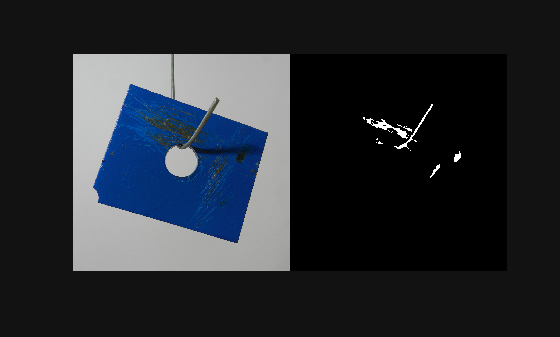

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.

currImg = readimage(partsDS, 57);
processedImg = ProcessImage(currImg);
InspectImage(currImg);
imshowpair(currImg, processedImg, "montage")


function [numComponents, maxArea, areaRatio] = InspectImage(img)
    defectMask = ProcessImage(img);
    numComponents = bwconncomp(defectMask); % Number of defects in the image (the hook is part of the mask, not 100% accurate)
    maxArea = regionprops(defectMask, "Area"); % Max area of each defect
    areaRatio = nnz(defectMask) / numel(defectMask); % The ratio of the area taken by all defects in comparison to the total area

end

function processedImg = ProcessImage(img)
    % Makes a mask of the background to remove it later
    bgMask = (img(:,:,1) < 120) & (img(:,:,2 < 120)); % Makes the actual mask, not 100% accurate
    bgMask = bwareaopen(~bgMask, 2000); % Inverts the mask for bwareaopen, removes stray pixels in the mask
    bgMask = ~bgMask;

    % Any Processing so the defects can more easily stand out
    processedImg = imflatfield(img, 1); % Helps to filter out shadows
    processedImg = im2gray(processedImg); % To grayscale

    filter = fspecial("average", 6); % Generally this filter works quite well to get rid of noise and flatten some colors, and is better than the matlab function in this case
    processedImg = imfilter(processedImg, filter);
    
    processedImg = imadjust(processedImg, [0.35 0.65]); % SUPER important contrast adjustment to isolate blue paint (good parts) from rust and scratches (bad parts)
    % ^^^ Contrast limits could be adjusted, but these are good.
    
    SE = strel("square", 3);
    processedImg = imopen(processedImg, SE);
    
    % Binarize the image, and remove the background
    processedImg = imbinarize(processedImg, "adaptive", "ForegroundPolarity", "dark");
    processedImg = processedImg .* bgMask; % Apply background mask to remove the background
    se = strel("disk", 4);
    processedImg = imerode(processedImg, se); % Helps to remove some of the border
    processedImg = bwareaopen(processedImg, 100); % Final clean up for removing the border
    
end

## Task 3: Train and Integrate an AI Classifier into your Single-Image Inspection Function

Your goal in this step is to use a MathWorks provided pretrained network (recommended: `resnet18`) to classify each part as either a PASS or FAIL, that will be part of the output of the function you began to build in the previous step.

- Load the recommended starter network: use `imagePretrainedNetwork` and select `resnet18` from the Deep Learning Toolbox.

- Resize/augment input with `augmentedImageDatastore(...)` to match the network input size.

- Fine-tune the last layers for your classes (start with `PASS` vs `FAIL`), using `trainNetwork(...)` or a guided workflow such as [Get started with transfer learning](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html) or [pretrained network workflows](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html).

- The output of your AI classification model should be a predicted label (PASS/FAIL) and a confidence score in that label

Deliverable: `[aiLabel, aiScore] = classify(net, roiForNet)` 

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.

%deepNetworkDesigner




function [aiLabel, aiScores] = classify(net, roiForNet)
    % You can write your function here 
end

## Task 3 Checkpoint: Combine outputs into a hybrid inspection result

Your image inspection function (e.g. `inspectPar(I)`) should combine the classical evidence with the AI classification output. 

In other words, your image inspection function should integrate both classical evidence from image processing and an AI classification decision. The AI classifier provides the main decision (PASS/FAIL) while the classical evidence extraction provides interpretability, traceability, and sanity checks for that decision.

Your function should return:

- `finalLabel` (from AI, in Task 3)

- `confidenceScore` (from AI, in Task 3)

- `evidenceOverlay` (from Step 4 in Task 2)

- `evidenceMetrics` (from Step 5 in Task 2)

- (optional) `baselineDecision` and a “disagreement flag” if optional rules in Step 6 from Task 2 and AI output disagree

Optionally, you can also choose to overlay these results on the image using `insertShape(...)` / `insertText(...)`, and save rejects with `imwrite(...)`

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.




function [finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecision] = inspectPart(I)
    % You can write your function here 
end

## Task 4: Evaluate Inspection System Performance

Now that you've built a hybrid inspection system that integrates classical evidence with an AI decision, your goal in this step is to test the system on a batch of images.

The results of this test should be summarized with a confusion matrix, report yield, and defect rates across the entire batch of images.

Write a script (e.g. `runInspectionSuite.m`) that:

- Splits data into train/test (e.g., `splitEachLabel(...)` or a fixed split)

- Evaluates the trained AI model and trains the inspection system on a test set and logs outcomes

- Produces a confusion matrix with `confusionmat(...)` / `confusionchart(...)`

- Summarizes yield and defect counts in tables and plots

- Visualizes common failure cases (e.g. by creating a montage of common errors using `montage(...)`)

% Here, it is recommended to create a separate runInspectionSuite.m file
% (or include as a local helper function) that combines the work you've done 
% so far here and additionally performs the steps outlined in the task description. 
% You can run it from here.





## Task 5: Test and Evaluate System Robustness

Your goal in this step is to assess how your system performs under simulated variations. You can simulate image inspection station variation by altering the lighting, blur, or noise in the images. Here are some suggested distortions to apply:

- Brightness/contrast: `imadjust(...)`

- Blur: `imgaussfilt(...)`

- Noise: `imnoise(...)`

Then, re-run the evaluation. In other words, run `runInspectionSuite.m `again with the same image set after applying distortions to the images.

Compare how performance changes across conditions by reporting how accuracy and false-reject rates change under simulated variations.

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.




## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

What are some limitations of your work?

What are practical next steps?